SHN_st.name='SHN'; 
SHN_st.lat=38.52;
SHN_st.lon=-78.43;
SHN_st.alt=1079;
SHN_st.env='con',

SHN_st = struct with fields:
    name: 'SHN'
     lat: 38.5200
     lon: -78.4300
     alt: 1079
     env: 'con'


SHN_st.footp='F';


SHN_rd=read_betsy('SHN_head',SHN_st.name);

datevec(SHN_rd.Time(1))

ans =         1996           7           2           0           0           0

datevec(SHN_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(SHN_rd.U_S,[5 50 95])

ans =    40.5738   77.7200   99.6550

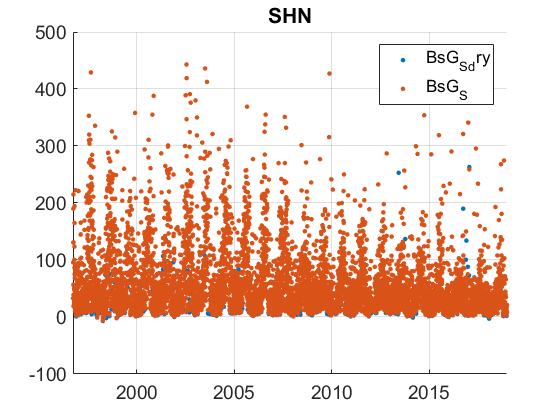

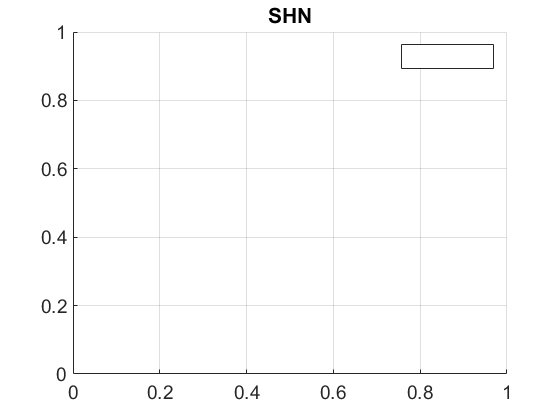

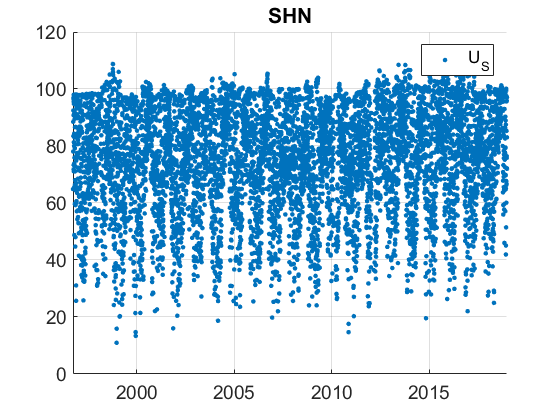

plotFigControl(SHN_rd,SHN_st.name);

% 1 size cut, TSP
% sc: ok, max in summer, few negatives
% dry --> no data in summer


% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE=[467;530;660]*ones(1,4);
% % %lambdaAE7=[370 470 520 590 660 880 950];
% % SHN_cal=compute_exp_SSA(SHN_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(SHN_cal, SHN_st.name);

%Questions:
%problems: no seems to be OK


% begin at the beginning of a year: 1997
%end 2018

SHN_tr=SHN_rd;
SHN_tr.y=year(SHN_tr.Time);
%eneleve une valeur de 2019
SHN_tr=SHN_tr(1:end-1,:);
% begin at the beginning of a year: 1994
%end: 2004
P=timerange('1997-01-01','2019-01-01');
SHN_tr=SHN_tr(P,:);

names=fieldnames(SHN_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    SHN_tr.(N{i})=[];
end


% dry: period (summer) without data

Iterating trend, loop:2, trend: -0.0056948/day = -2.08/year
Iterating trend, loop:3, trend: -0.0058243/day = -2.1273/year
Iteration stopped, trend: -0.0058244/day = -2.1274/year
Final estimate on noise autocorrelation=0.31293, Noise standard deviation:19.1191
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0072883  -0.0044147]/day = [-2.6621     -1.6125]/yr
Round:200/500, Trend BCI: [-0.0072883  -0.0043907]/day = [-2.6621     -1.6037]/yr
Round:300/500, Trend BCI: [-0.0072837  -0.0043033]/day = [-2.6604     -1.5718]/yr
Round:400/500, Trend BCI: [-0.0072837  -0.0042432]/day = [-2.6604     -1.5498]/yr
Round:500/500, Trend BCI: [-0.0073234   -0.004273]/day = [-2.6749     -1.5607]/yr
Trend BCI: [-0.0073234   -0.004273]/day = [-2.6749     -1.5607]/yr
Iterating trend, loop:2, trend: -0.0073015/day = -2.6669/year
Iterating trend, loop:3, trend: -0.0078651/day = -2.8727/year
Iteration stopped, trend: -0.0078683/day = -2.8739/year
Final estimate on noise autocorrelation=0.38004, Noise sta

Iterating trend, loop:2, trend: -0.0056083/day = -2.0484/year
Iterating trend, loop:3, trend: -0.0060871/day = -2.2233/year
Iteration stopped, trend: -0.006088/day = -2.2237/year
Final estimate on noise autocorrelation=0.056192, Noise standard deviation:9.694
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0078656  -0.0044581]/day = [-2.8729     -1.6283]/yr
Round:200/500, Trend BCI: [-0.007794  -0.0039873]/day = [-2.8467     -1.4564]/yr
Round:300/500, Trend BCI: [-0.0076903  -0.0042032]/day = [-2.8089     -1.5352]/yr
Round:400/500, Trend BCI: [-0.007687  -0.0042787]/day = [-2.8077     -1.5628]/yr
Round:500/500, Trend BCI: [-0.0077221  -0.0043099]/day = [-2.8205     -1.5742]/yr
Trend BCI: [-0.0077221  -0.0043099]/day = [-2.8205     -1.5742]/yr


Iterating trend, loop:2, trend: -0.0060402/day = -2.2062/year
Iterating trend, loop:3, trend: -0.006608/day = -2.4136/year
Iteration stopped, trend: -0.0066085/day = -2.4138/year
Final estimate on noise autocorrelation=0.0082671, Noise standard deviation:11.9366
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0088207  -0.0043532]/day = [-3.2218       -1.59]/yr
Round:200/500, Trend BCI: [-0.0087155  -0.0043532]/day = [-3.1833       -1.59]/yr
Round:300/500, Trend BCI: [-0.0086792  -0.0043532]/day = [-3.1701       -1.59]/yr
Round:400/500, Trend BCI: [-0.0086959  -0.0044638]/day = [-3.1762     -1.6304]/yr
Round:500/500, Trend BCI: [-0.0086764  -0.0044967]/day = [-3.1691     -1.6424]/yr
Trend BCI: [-0.0086764  -0.0044967]/day = [-3.1691     -1.6424]/yr
Iterating trend, loop:2, trend: -0.0055248/day = -2.0179/year
Iterating trend, loop:3, trend: -0.0064104/day = -2.3414/year
Iteration stopped, trend: -0.0064166/day = -2.3437/year
Final estimate on noise autocorrelation=0.1856, Noise s

Iterating trend, loop:2, trend: 0.0010926/day = 0.39906/year
Iterating trend, loop:3, trend: 0.0015447/day = 0.56421/year
Iteration stopped, trend: 0.0015449/day = 0.56429/year
Final estimate on noise autocorrelation=0.093372, Noise standard deviation:19.479
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0020541   0.0062262]/day = [-0.75026      2.2741]/yr
Round:200/500, Trend BCI: [-0.0020259   0.0060544]/day = [-0.73997      2.2114]/yr
Round:300/500, Trend BCI: [-0.0019883   0.0055074]/day = [-0.72621      2.0116]/yr
Round:400/500, Trend BCI: [-0.0019416   0.0053935]/day = [-0.70916        1.97]/yr
Round:500/500, Trend BCI: [-0.002075    0.005317]/day = [-0.75788       1.942]/yr
Trend BCI: [-0.002075    0.005317]/day = [-0.75788       1.942]/yr


Iterating trend, loop:2, trend: 0.00041479/day = 0.1515/year
Iterating trend, loop:3, trend: 0.00045294/day = 0.16544/year
Iteration stopped, trend: 0.00045296/day = 0.16544/year
Final estimate on noise autocorrelation=0.02154, Noise standard deviation:7.894
Starting MC. rounds: 500
Round:100/500, Trend BCI: [7.1672e-05  0.00086341]/day = [0.026178     0.31536]/yr
Round:200/500, Trend BCI: [4.849e-06  0.00084127]/day = [0.0017711     0.30727]/yr
Round:300/500, Trend BCI: [3.0907e-05  0.00089002]/day = [0.011289     0.32508]/yr
Round:400/500, Trend BCI: [2.2417e-05  0.00089002]/day = [0.0081879     0.32508]/yr
Round:500/500, Trend BCI: [3.3633e-05  0.00088598]/day = [0.012284      0.3236]/yr
Trend BCI: [3.3633e-05  0.00088598]/day = [0.012284      0.3236]/yr
Iterating trend, loop:2, trend: 0.000481/day = 0.17569/year
Iterating trend, loop:3, trend: 0.00045616/day = 0.16661/year
Iteration stopped, trend: 0.00045615/day = 0.16661/year
Final estimate on noise autocorrelation=-0.085468, Noi

Iterating trend, loop:2, trend: 0.00084305/day = 0.30792/year
Iterating trend, loop:3, trend: 0.00089792/day = 0.32797/year
Iteration stopped, trend: 0.00089795/day = 0.32798/year
Final estimate on noise autocorrelation=-0.11554, Noise standard deviation:7.6065
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-1.0295e-05-1.1469e-05i     0.002037+4.4157e-06i]/day = [-0.0037602-0.004189i       0.74401+0.0016128i]/yr
Round:200/500, Trend BCI: [5.3319e-05+4.9053e-06i    0.0020564-2.3327e-06i]/day = [0.019475+0.0017917i      0.75111-0.00085201i]/yr
Round:300/500, Trend BCI: [6.0711e-05-1.0732e-05i    0.0020564-2.3327e-06i]/day = [0.022175-0.0039197i      0.75111-0.00085201i]/yr
Round:400/500, Trend BCI: [-6.7087e-05+3.928e-07i    0.0020537-7.5635e-06i]/day = [-0.024503+0.00014347i       0.75012-0.0027626i]/yr
Round:500/500, Trend BCI: [1.3865e-06+1.0124e-05i    0.0020665-1.2731e-05i]/day = [0.00050641+0.003698i       0.75478-0.0046499i]/yr
Trend BCI: [1.3865e-06+1.0124e-05i    0.0020665-

Iterating trend, loop:2, trend: 0.0018063/day = 0.65974/year
Iterating trend, loop:3, trend: 0.001664/day = 0.60776/year
Iteration stopped, trend: 0.0016637/day = 0.60765/year
Final estimate on noise autocorrelation=-0.11504, Noise standard deviation:7.6356
Starting MC. rounds: 500
Round:100/500, Trend BCI: [0.00053819-4.2751e-06i    0.0028322+7.5332e-06i]/day = [0.19657-0.0015615i        1.0345+0.0027515i]/yr
Round:200/500, Trend BCI: [0.00059717+1.2349e-05i    0.0028169+6.1513e-06i]/day = [0.21812+0.0045103i        1.0289+0.0022468i]/yr
Round:300/500, Trend BCI: [0.00058531+2.938e-06i    0.0028287+1.3944e-06i]/day = [0.21378+0.0010731i        1.0332+0.0005093i]/yr
Round:400/500, Trend BCI: [-1.1063e-06+6.5254e-06i    0.0028077+9.1632e-06i]/day = [-0.00040407+0.0023834i        1.0255+0.0033469i]/yr
Round:500/500, Trend BCI: [0.00051851-6.1141e-06i    0.0028369+8.2749e-07i]/day = [0.18939-0.0022332i       1.0362+0.00030224i]/yr
Trend BCI: [0.00051851-6.1141e-06i    0.0028369+8.2749e-07

Iterating trend, loop:2, trend: 0.0018752/day = 0.68493/year
Iterating trend, loop:3, trend: 0.0018234/day = 0.66598/year
Iteration stopped, trend: 0.0018233/day = 0.66596/year
Final estimate on noise autocorrelation=-0.14111, Noise standard deviation:7.6029
Starting MC. rounds: 500
Round:100/500, Trend BCI: [0.00056919+6.7711e-06i    0.0029862+1.0306e-05i]/day = [0.2079+0.0024731i        1.0907+0.0037641i]/yr
Round:200/500, Trend BCI: [0.0006202+5.3485e-06i    0.0029186-6.1668e-07i]/day = [0.22653+0.0019535i        1.066-0.00022524i]/yr
Round:300/500, Trend BCI: [0.00067658+1.0993e-06i    0.0029078-7.7181e-06i]/day = [0.24712+0.00040152i         1.0621-0.002819i]/yr
Round:400/500, Trend BCI: [0.00069292-1.271e-05i      0.00294+1.0761e-05i]/day = [0.25309-0.0046425i        1.0738+0.0039305i]/yr
Round:500/500, Trend BCI: [0.00072049+7.4825e-06i    0.0029605+2.5183e-05i]/day = [0.26316+0.002733i        1.0813+0.0091982i]/yr
Trend BCI: [0.00072049+7.4825e-06i    0.0029605+2.5183e-05i]/day

Iterating trend, loop:2, trend: 0.00014144/day = 0.051662/year
Iterating trend, loop:3, trend: 5.5093e-05/day = 0.020123/year
Iteration stopped, trend: 5.501e-05/day = 0.020093/year
Final estimate on noise autocorrelation=-0.10635, Noise standard deviation:8.527
Starting MC. rounds: 500
Round:100/500, Trend BCI: [8.0141e-05-3.2388e-06i   3.8072e-05+6.5154e-06i]/day = [0.029271-0.001183i      0.013906+0.0023798i]/yr
Round:200/500, Trend BCI: [-3.2309e-06+1.9141e-06i    3.4377e-05+6.334e-06i]/day = [-0.0011801+0.00069911i      0.012556+0.0023135i]/yr
Round:300/500, Trend BCI: [-6.9559e-05-3.8836e-06i   3.7854e-06-9.6021e-06i]/day = [-0.025407-0.0014185i     0.0013826-0.0035072i]/yr
Round:400/500, Trend BCI: [5.8902e-05+2.8071e-06i    0.0015971+9.0434e-06i]/day = [0.021514+0.0010253i       0.58336+0.0033031i]/yr
Round:500/500, Trend BCI: [3.753e-06-2.0066e-06i   4.1081e-06+8.5142e-06i]/day = [0.0013708-0.00073289i     0.0015005+0.0031098i]/yr
Trend BCI: [3.753e-06-2.0066e-06i   4.1081e-06

Iterating trend, loop:2, trend: -0.00074605/day = -0.2725/year
Iterating trend, loop:3, trend: -0.00070694/day = -0.25821/year
Iteration stopped, trend: -0.00070692/day = -0.2582/year
Final estimate on noise autocorrelation=-0.059036, Noise standard deviation:7.968
Starting MC. rounds: 500
Round:100/500, Trend BCI: [0.00011475+4.9054e-06i   -0.0019295+4.0809e-06i]/day = [0.041912+0.0017917i      -0.70474+0.0014906i]/yr
Round:200/500, Trend BCI: [-3.9507e-06+3.8559e-06i   -0.0018462-5.1415e-06i]/day = [-0.001443+0.0014083i      -0.67434-0.0018779i]/yr
Round:300/500, Trend BCI: [0.00010978+6.9535e-06i   -0.0018756+6.4839e-07i]/day = [0.040098+0.0025398i     -0.68506+0.00023682i]/yr
Round:400/500, Trend BCI: [1.2858e-06-3.631e-06i   -0.0018462-5.1415e-06i]/day = [0.00046964-0.0013262i      -0.67434-0.0018779i]/yr
Round:500/500, Trend BCI: [-1.1155e-07-3.2368e-06i   -0.0018844-6.4858e-06i]/day = [-4.0742e-05-0.0011822i      -0.68829-0.0023689i]/yr
Trend BCI: [-1.1155e-07-3.2368e-06i   -0.0

Iterating trend, loop:2, trend: 0.00033186/day = 0.12121/year
Iterating trend, loop:3, trend: 0.00040031/day = 0.14621/year
Iteration stopped, trend: 0.00040037/day = 0.14623/year
Final estimate on noise autocorrelation=0.2084, Noise standard deviation:8.1351
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0011361   0.0017623]/day = [-0.41495     0.64367]/yr
Round:200/500, Trend BCI: [-0.0015343   0.0018383]/day = [-0.56039     0.67144]/yr
Round:300/500, Trend BCI: [-0.0014053   0.0018523]/day = [-0.51329     0.67656]/yr
Round:400/500, Trend BCI: [-0.0013636   0.0019082]/day = [-0.49805     0.69695]/yr
Round:500/500, Trend BCI: [-0.0013072   0.0019418]/day = [-0.47747     0.70925]/yr
Trend BCI: [-0.0013072   0.0019418]/day = [-0.47747     0.70925]/yr


Iterating trend, loop:2, trend: 0.0027302/day = 0.99719/year
Iterating trend, loop:3, trend: 0.002601/day = 0.95003/year
Iteration stopped, trend: 0.0026001/day = 0.94968/year
Final estimate on noise autocorrelation=0.12987, Noise standard deviation:27.0578
Starting MC. rounds: 500
Round:100/500, Trend BCI: [0.00059851   0.0044521]/day = [0.21861      1.6261]/yr
Round:200/500, Trend BCI: [0.00081137   0.0043617]/day = [0.29635      1.5931]/yr
Round:300/500, Trend BCI: [0.00059851   0.0044521]/day = [0.21861      1.6261]/yr
Round:400/500, Trend BCI: [0.00070906   0.0044817]/day = [0.25898      1.6369]/yr
Round:500/500, Trend BCI: [0.00070906   0.0044817]/day = [0.25898      1.6369]/yr
Trend BCI: [0.00070906   0.0044817]/day = [0.25898      1.6369]/yr
Iterating trend, loop:2, trend: 0.0051196/day = 1.8699/year
Iterating trend, loop:3, trend: 0.0048188/day = 1.7601/year
Iteration stopped, trend: 0.004815/day = 1.7587/year
Final estimate on noise autocorrelation=0.14438, Noise standard dev

Iterating trend, loop:2, trend: 0.0077183/day = 2.8191/year
Iterating trend, loop:3, trend: 0.0073978/day = 2.702/year
Iteration stopped, trend: 0.0073906/day = 2.6994/year
Final estimate on noise autocorrelation=0.11568, Noise standard deviation:35.1446
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00048421    0.015303]/day = [-0.17686      5.5893]/yr
Round:200/500, Trend BCI: [-0.00035206    0.015227]/day = [-0.12859      5.5618]/yr
Round:300/500, Trend BCI: [0.00031252    0.015108]/day = [0.11415      5.5184]/yr
Round:400/500, Trend BCI: [-0.00035206    0.014643]/day = [-0.12859      5.3482]/yr
Round:500/500, Trend BCI: [-0.00035206    0.014703]/day = [-0.12859      5.3702]/yr
Trend BCI: [-0.00035206    0.014703]/day = [-0.12859      5.3702]/yr


Iterating trend, loop:2, trend: 0.0069773/day = 2.5485/year
Iterating trend, loop:3, trend: 0.006458/day = 2.3588/year
Iteration stopped, trend: 0.0064484/day = 2.3553/year
Final estimate on noise autocorrelation=0.053161, Noise standard deviation:25.1981
Starting MC. rounds: 500
Round:100/500, Trend BCI: [0.00053272    0.011368]/day = [0.19458       4.152]/yr
Round:200/500, Trend BCI: [0.00060197    0.011538]/day = [0.21987      4.2144]/yr
Round:300/500, Trend BCI: [0.00074484    0.011887]/day = [0.27205      4.3416]/yr
Round:400/500, Trend BCI: [0.00067083    0.011887]/day = [0.24502      4.3416]/yr
Round:500/500, Trend BCI: [0.00067083    0.011777]/day = [0.24502      4.3015]/yr
Trend BCI: [0.00067083    0.011777]/day = [0.24502      4.3015]/yr


Iterating trend, loop:2, trend: 0.0031717/day = 1.1585/year
Iterating trend, loop:3, trend: 0.0030992/day = 1.132/year
Iteration stopped, trend: 0.003098/day = 1.1315/year
Final estimate on noise autocorrelation=0.35898, Noise standard deviation:14.5205
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0006696      0.0081]/day = [-0.24457      2.9585]/yr
Round:200/500, Trend BCI: [-0.00077155      0.0081]/day = [-0.28181      2.9585]/yr
Round:300/500, Trend BCI: [-0.00089481   0.0075109]/day = [-0.32683      2.7434]/yr
Round:400/500, Trend BCI: [-0.00091247   0.0074366]/day = [-0.33328      2.7162]/yr
Round:500/500, Trend BCI: [-0.00096362   0.0074366]/day = [-0.35196      2.7162]/yr
Trend BCI: [-0.00096362   0.0074366]/day = [-0.35196      2.7162]/yr


Iterating trend, loop:2, trend: 0.004137/day = 1.511/year
Iterating trend, loop:3, trend: 0.0040396/day = 1.4755/year
Iteration stopped, trend: 0.0040366/day = 1.4744/year
Final estimate on noise autocorrelation=0.36365, Noise standard deviation:14.2933
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-6.2038e-05    0.007153]/day = [-0.022659      2.6126]/yr
Round:200/500, Trend BCI: [-0.00047685   0.0074093]/day = [-0.17417      2.7062]/yr
Round:300/500, Trend BCI: [-1.4692e-05   0.0082062]/day = [-0.0053663      2.9973]/yr
Round:400/500, Trend BCI: [2.3916e-05   0.0082062]/day = [0.0087354      2.9973]/yr
Round:500/500, Trend BCI: [2.3916e-05   0.0083162]/day = [0.0087354      3.0375]/yr
Trend BCI: [2.3916e-05   0.0083162]/day = [0.0087354      3.0375]/yr


Iterating trend, loop:2, trend: -0.0006021/day = -0.21992/year
Iterating trend, loop:3, trend: -0.0006595/day = -0.24088/year
Iteration stopped, trend: -0.00066056/day = -0.24127/year
Final estimate on noise autocorrelation=0.36452, Noise standard deviation:6.5463
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0027037   0.0014923]/day = [-0.98753     0.54505]/yr
Round:200/500, Trend BCI: [-0.0027734   0.0013003]/day = [-1.013     0.47494]/yr
Round:300/500, Trend BCI: [-0.0025461   0.0010785]/day = [-0.92995     0.39391]/yr
Round:400/500, Trend BCI: [-0.0025461   0.0010619]/day = [-0.92995     0.38787]/yr
Round:500/500, Trend BCI: [-0.0025755   0.0011134]/day = [-0.94069     0.40665]/yr
Trend BCI: [-0.0025755   0.0011134]/day = [-0.94069     0.40665]/yr


Iterating trend, loop:2, trend: -0.0013276/day = -0.48491/year
Iterating trend, loop:3, trend: -0.0013703/day = -0.50049/year
Iteration stopped, trend: -0.0013714/day = -0.50091/year
Final estimate on noise autocorrelation=0.10783, Noise standard deviation:7.8246
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0031941 -2.6745e-05]/day = [-1.1666  -0.0097687]/yr
Round:200/500, Trend BCI: [-0.0030379  0.00014377]/day = [-1.1096    0.052511]/yr
Round:300/500, Trend BCI: [-0.0030205  0.00016063]/day = [-1.1032    0.058669]/yr
Round:400/500, Trend BCI: [-0.0030589  0.00014377]/day = [-1.1172    0.052511]/yr
Round:500/500, Trend BCI: [-0.0030155  0.00017553]/day = [-1.1014    0.064114]/yr
Trend BCI: [-0.0030155  0.00017553]/day = [-1.1014    0.064114]/yr


Iterating trend, loop:2, trend: -0.0020287/day = -0.74099/year
Iterating trend, loop:3, trend: -0.0018104/day = -0.66123/year
Iteration stopped, trend: -0.0018091/day = -0.66078/year
Final estimate on noise autocorrelation=-0.019413, Noise standard deviation:9.6344
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-2.643e-05-9.3408e-07i    -0.003504-1.6642e-06i]/day = [-0.0096536-0.00034117i      -1.2798-0.00060783i]/yr
Round:200/500, Trend BCI: [-1.5365e-06-5.1329e-06i   -0.0036042-1.3444e-06i]/day = [-0.00056121-0.0018748i      -1.3164-0.00049105i]/yr
Round:300/500, Trend BCI: [-1.5365e-06-5.1329e-06i   -0.0037014+8.2099e-07i]/day = [-0.00056121-0.0018748i      -1.3519+0.00029987i]/yr
Round:400/500, Trend BCI: [0.00020358+5.0193e-07i   -0.0036331-3.9238e-06i]/day = [0.074357+0.00018333i        -1.327-0.0014332i]/yr
Round:500/500, Trend BCI: [0.00021062+3.8176e-06i   -0.0036331-3.9238e-06i]/day = [0.076928+0.0013944i        -1.327-0.0014332i]/yr
Trend BCI: [0.00021062+3.8176e-06i   

Iterating trend, loop:2, trend: -0.0012021/day = -0.43907/year
Iterating trend, loop:3, trend: -0.0012234/day = -0.44685/year
Iteration stopped, trend: -0.0012237/day = -0.44695/year
Final estimate on noise autocorrelation=-0.050963, Noise standard deviation:10.3982
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-3.2817e-05+7.2613e-07i   -0.0033556-1.3864e-05i]/day = [-0.011986+0.00026522i       -1.2256-0.0050639i]/yr
Round:200/500, Trend BCI: [-0.00017358-7.6025e-06i   -0.0031236+4.3291e-06i]/day = [-0.0634-0.0027768i       -1.1409+0.0015812i]/yr
Round:300/500, Trend BCI: [3.8332e-06-4.0707e-06i   -0.0030894+7.2825e-06i]/day = [0.0014001-0.0014868i       -1.1284+0.0026599i]/yr
Round:400/500, Trend BCI: [2.6418e-06+1.3642e-05i   -0.0031236+4.3291e-06i]/day = [0.0009649+0.0049828i       -1.1409+0.0015812i]/yr
Round:500/500, Trend BCI: [0.00013146+7.119e-06i   -0.0031427-1.7909e-06i]/day = [0.048014+0.0026002i      -1.1479-0.00065413i]/yr
Trend BCI: [0.00013146+7.119e-06i   -0.00314

Iterating trend, loop:2, trend: -0.00015901/day = -0.058077/year
Iterating trend, loop:3, trend: -0.00028472/day = -0.10399/year
Iterating trend, loop:4, trend: -0.00028858/day = -0.1054/year
Iteration stopped, trend: -0.00028866/day = -0.10543/year
Final estimate on noise autocorrelation=-0.13074, Noise standard deviation:10.0843
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-6.308e-06-2.2394e-06i   0.00016339-5.5489e-06i]/day = [-0.002304-0.00081795i      0.059677-0.0020267i]/yr
Round:200/500, Trend BCI: [-5.4774e-05+3.2104e-06i   -0.0021275+2.2493e-05i]/day = [-0.020006+0.0011726i      -0.77707+0.0082154i]/yr
Round:300/500, Trend BCI: [6.219e-06-1.6598e-05i   -0.0021275+2.2493e-05i]/day = [0.0022715-0.0060623i      -0.77707+0.0082154i]/yr
Round:400/500, Trend BCI: [4.6489e-07+8.0553e-06i    0.0021608-4.4645e-05i]/day = [0.0001698+0.0029422i        0.78922-0.016306i]/yr
Round:500/500, Trend BCI: [-3.6048e-06+2.8261e-05i    0.0021554-2.2608e-05i]/day = [-0.0013167+0.010322i     

Iterating trend, loop:2, trend: -0.00089818/day = -0.32806/year
Iterating trend, loop:3, trend: -0.00056375/day = -0.20591/year
Iteration stopped, trend: -0.00055839/day = -0.20395/year
Final estimate on noise autocorrelation=-0.17795, Noise standard deviation:9.8367
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-2.0651e-05+1.7008e-05i   -0.0023755+1.8464e-05i]/day = [-0.0075429+0.0062122i      -0.86764+0.0067441i]/yr
Round:200/500, Trend BCI: [6.5293e-05+3.8327e-05i   -0.0023182-6.5961e-06i]/day = [0.023848+0.013999i      -0.84674-0.0024092i]/yr
Round:300/500, Trend BCI: [-7.9022e-05+2.3302e-05i   -0.0022261-1.0021e-05i]/day = [-0.028863+0.008511i      -0.81308-0.0036602i]/yr
Round:400/500, Trend BCI: [-7.9022e-05+2.3302e-05i   -0.0022261-1.0021e-05i]/day = [-0.028863+0.008511i      -0.81308-0.0036602i]/yr
Round:500/500, Trend BCI: [1.9773e-07-1.7061e-05i   -0.0022403+3.0637e-05i]/day = [7.2219e-05-0.0062316i        -0.81826+0.01119i]/yr
Trend BCI: [1.9773e-07-1.7061e-05i   -0.0

Iterating trend, loop:2, trend: -0.00072579/day = -0.2651/year
Iterating trend, loop:3, trend: -0.0005873/day = -0.21451/year
Iteration stopped, trend: -0.00058686/day = -0.21435/year
Final estimate on noise autocorrelation=-0.29442, Noise standard deviation:12.2468
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-1.0145e-06-5.3372e-07i   -0.0021629+4.0718e-05i]/day = [-0.00037055-0.00019494i       -0.79001+0.014872i]/yr
Round:200/500, Trend BCI: [-1.0145e-06-5.3372e-07i   -0.0023774+3.8087e-05i]/day = [-0.00037055-0.00019494i       -0.86836+0.013911i]/yr
Round:300/500, Trend BCI: [-1.4775e-06-6.8957e-06i   -0.0024114-1.2457e-05i]/day = [-0.00053967-0.0025186i      -0.88075-0.0045499i]/yr
Round:400/500, Trend BCI: [4.8462e-05+3.1929e-05i   -0.0024028+8.1286e-05i]/day = [0.017701+0.011662i        -0.87763+0.02969i]/yr
Round:500/500, Trend BCI: [-1.31e-05-2.8419e-05i   -0.0024028+8.1286e-05i]/day = [-0.0047846-0.01038i        -0.87763+0.02969i]/yr
Trend BCI: [-1.31e-05-2.8419e-05i   

Iterating trend, loop:2, trend: 0.00028811/day = 0.10523/year
Iterating trend, loop:3, trend: 0.0003015/day = 0.11012/year
Iteration stopped, trend: 0.00030164/day = 0.11017/year
Final estimate on noise autocorrelation=-0.25377, Noise standard deviation:12.3184
Starting MC. rounds: 500
Round:100/500, Trend BCI: [0.00013821+3.7736e-05i   1.2961e-05+4.6995e-06i]/day = [0.05048+0.013783i      0.004734+0.0017165i]/yr
Round:200/500, Trend BCI: [-0.00015196+5.5135e-05i    0.0022578-4.2839e-06i]/day = [-0.055504+0.020138i       0.82467-0.0015647i]/yr
Round:300/500, Trend BCI: [2.5823e-05+5.8792e-05i    0.0022791-4.3626e-05i]/day = [0.0094317+0.021474i        0.83245-0.015934i]/yr
Round:400/500, Trend BCI: [-2.3493e-05+5.2341e-05i     0.0023052-6.104e-05i]/day = [-0.008581+0.019118i        0.84199-0.022295i]/yr
Round:500/500, Trend BCI: [-6.3356e-05+5.4119e-05i    0.0022656-1.8043e-05i]/day = [-0.023141+0.019767i        0.8275-0.0065901i]/yr
Trend BCI: [-6.3356e-05+5.4119e-05i    0.0022656-1.8

SHN_result = 225×9 table
    station    end_time    length_period    granularity    parameter    instrument    MK_seasonality    method      results   
    _______    ________    _____________    ___________    _________    __________    ______________    ______    ____________
    'SHN'      2017        10               'daily'        'BsG_S'      'neph'        'y'               'MK'      [1×1 struct]
    'SHN'      2017        10               'daily'        'BsG_S'      'neph'        'MetSea'          'MK'      [1×1 struct]
    'SHN'      2017        10               'daily'        'BsG_S'      'neph'        'month'           'MK'      [1×1 struct]
    'SHN'      2017        15     

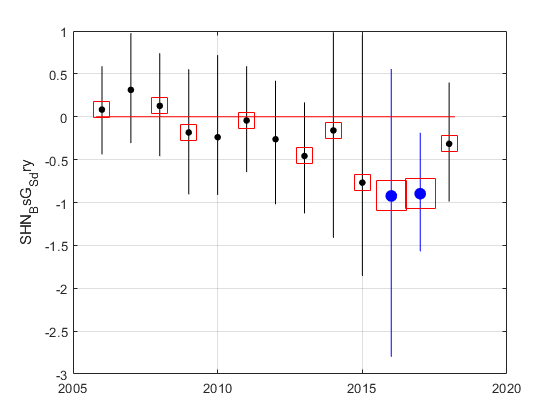

SHN_result= all_trend_STN(SHN_tr,SHN_st); 

SHN_result_D=SHN_result;